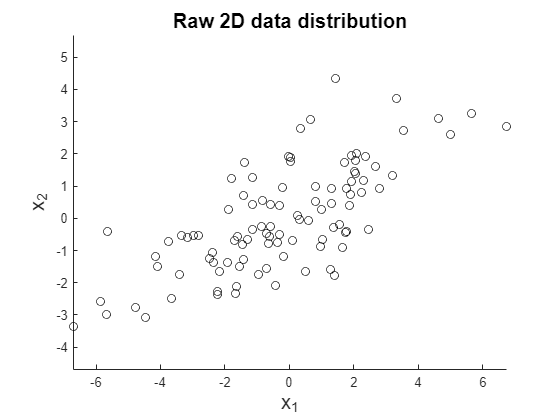

clear all;
close all;

% Generate linear 2D data
x(1,:) = randn(1,100);
x(2,:) = randn(1,100)*3;
[p(1,:),p(2,:)] = cart2pol(x(1,:),x(2,:));
p(1,:) = p(1,:)-pi/3;
[x(1,:),x(2,:)] = pol2cart(p(1,:),p(2,:));

scatter(x(1,:),x(2,:), 'ok');
title('Raw 2D data distribution', 'FontSize',15);
xlabel('x_1','FontSize',15); ylabel('x_2', 'FontSize',15);
axis equal;


Mx=mean(x,2);
X=x-Mx;
Sd=std(x');
Xn(1,:)=X(1,:)./Sd(1);Xn(2,:)=X(2,:)./Sd(2);
S=cov(X')

S =           6.34700013908007          2.95335891637486
          2.95335891637486          2.67177324316322


Sn=cov(Xn')

Sn =                          1         0.717186617516822
         0.717186617516822                         1




R = corrcoef(X')

R =                          1         0.717186617516822
         0.717186617516822                         1


Rn = corrcoef(Xn')

Rn =                          1         0.717186617516822
         0.717186617516822                         1


[V,D] = eig(S)

V =          0.485646355885682        -0.874155373497731
        -0.874155373497731        -0.485646355885682


D =           1.03100314800157                         0
                         0          7.98777023424172
